## Programación No-Lineal: Problema de minimización

### Problema 10: Minimización de costos para encontrar la política óptima de reemplazo de un equipo. 

Primero obtenemos los datos de las funciones para encontrar los parámetros de nuestras funciones S(t) y U(t)

Insertamos los valores de las funciones evaluadas en dos puntos y esos dos puntos. El programa realiza el despeje para las constantes de las funciones. 

datoCmin = 5000;
datosCmax  = 5500;
tcmin =0.5;
tcmax =1;
divt1 = tcmax-tcmin;
datosCdiv = datosCmax/datoCmin;
b = log(datosCdiv)/divt1
a = datosCmax/exp(b*tcmax)

%Ojo ya que la exponencial de S(t) tiene argumento negativo el datos con nombre max siempre será menor
datosSmin = 200000;
datosSmax = 180000;
tsmin = 1;
tsmax = 2;
divt2 = tsmax-tsmin;
datosSdiv = datosSmax/datosSmin;
d = -log(datosSdiv)/divt2
c = datosSmax/exp(-d*tsmax)

K = c


Creamos las funciones con las constantes anteriormente obtenidas. 

syms t
funS = @(t) c*exp(-d*t);
funC = @(t) a*exp(b*t);

Linea auxiliar debido a que la función G de costos incluye una integral, por ello debemos obtener el resultado simbólico de la integral y convertirlo a función del tiempo

funCintegrada = matlabFunction(int(funC,0,t))


Creamos la función G(t) y la graficamos en un intervalo limitado

G = @(t) K/t + 1/t*funCintegrada(t) -funS(t)/t
fplot(G, [1,20])
axis([0 20 0 70000])

Observamos que el mínimo sucede alrrededor del cinco, debemos dar esto como parámetros a nuestro método Newton Rhapson junto con la función G para encontrar el mínimo. 

La función genera el tiempo óptimo así como el valor de la función objetivo en ese punto. 

[tOpt, fObj] = newtonRaphsonMinimo(G, 5)

### Enfoque de Utilizades Desarrollado en el Curso. 

Tenemos las funciones de distancia

syms k
funI = @(k)  12750*exp(0.0013*k); %Función de Ingreso
funC = @(k)   9000*exp(0.002*k);  %Función de Costos
funS = @(k) 250000*exp(-0.005*k)  %Valor de Rescate del Automovil
K = 275000;                       %Costo de Reposición del Automovil

Lineas auxiliares debido a que la función U(k) de utilidad incluye una integral, por ello debemos obtener el resultado simbólico de la integral y convertirlo a función de la distancia k.

funIintegrada = matlabFunction(int(funI,0,k))
funCintegrada = matlabFunction(int(funC,0,k))

Creamos la función de utilidades U(k) y la graficamos en un intervalo limitado

U = @(k) funIintegrada(k) - funCintegrada(k) + funS(k) - K
fplot(U)
axis([0 1000 -1000000 1000000])

Observamos que el mínimo sucede alrrededor del cinco, debemos dar esto como parámetros a nuestro método Newton Rhapson junto con la función G para encontrar el mínimo. 

La función genera el tiempo óptimo así como el valor de la función objetivo en ese punto. 

[tOpt, fObj] = newtonRaphsonMinimo(U, 500)

## Mantenimiento:

### 
$$G\left(t\right)=\frac{\left(C_1 F\left(t\right)+C_2 R\left(t\right)\right)}{H\left(t\right)+t\;R\left(t\right)}$$


### Ejemplo 1: Uniforme (Problema 5)

syms t
F = @(t)  t/1000;
R = @(t)  1-t/1000;
f = @(t) matlabFunction(diff(F,t))
exprH = @(t) t*f(t)
H = matlabFunction(int(exprH,0,t));
C1 = 500; %Costo de mantenimiento Correctivo
C2 = 100; %Costo de mantenimineto Predictivo

G = @(t) (C1*F(t) + C2*R(t))/(H(t)+t*R(t))
fplot(G, [0,1000])

[tOpt, fObj] = newtonRaphsonMinimo(G, 500)

### Ejemplo 2: Exponenciales en Paralelo (Problema 7)

syms t
F = @(t)  1-2*exp(-t) + exp(-2*t)

F = function_handle with value:
    @(t)1-2*exp(-t)+exp(-2*t)


R = @(t)  1- F(t)

R = function_handle with value:
    @(t)1-F(t)


f = @(t) matlabFunction(diff(F,t))

f = function_handle with value:
    @(t)matlabFunction(diff(F,t))


exprH = @(t) t*f(t)

exprH = function_handle with value:
    @(t)t*f(t)


H = matlabFunction(int(exprH,0,t))

H = function_handle with value:
    @(t)exp(-t).*(t+1.0).*-2.0+(exp(t.*-2.0).*(t.*2.0+1.0))./2.0+3.0./2.0


C1 = 90; %Costo de mantenimiento Correctivo
C2 = 3; %Costo de mantenimineto Predictivo

G = @(t) (C1*F(t) + C2*R(t))/(H(t)+t*R(t))

G = function_handle with value:
    @(t)(C1*F(t)+C2*R(t))/(H(t)+t*R(t))


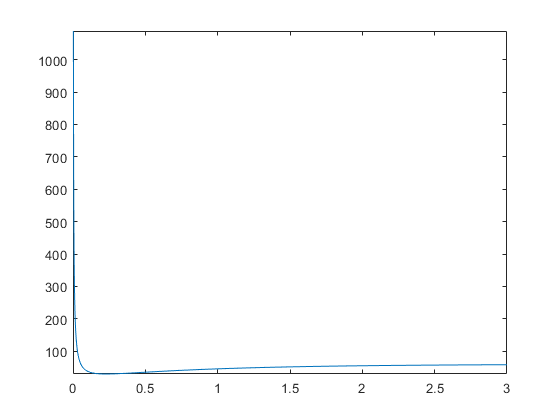

fplot(G, [0,3])


[tOpt, fObj] = newtonRaphsonMinimo(G, 0.3)

tOpt = 0.2278

fObj = 29.4500

### Nueva función: Expresión de Utilidad


$$\Pi \left(t\right)=G\;\int_0^t R\left(\xi \right)d\xi -C_1 *F\left(t\right)-C_2 *R\left(t\right)$$


## Nueva Función: Análisis de la función de Costos para la Exponencial.


$$G\left(t\right)=\frac{\left(C_1 F\left(t\right)+C_2 R\left(t\right)\right)}{\int_0^t R\left(t\right)}$$


syms t
C1 = 100;
C2 = 10;
%exp con alpha = -0.01

alpha = -0.01;
f = @(t) alpha*exp(alpha*t)

f = function_handle with value:
    @(t)(alpha*exp(alpha*t)).^2


F = matlabFunction(int(f, 0, t))

F = function_handle with value:
    @(t)exp(t.*(-1.0./5.0e+2)).*(-5.0e-4)+5.0e-4


R = @(t) 1- F(t)

R = function_handle with value:
    @(t)1-F(t)


interR = matlabFunction(int(R, 0, t))

interR = function_handle with value:
    @(t)t.*9.995e-1-exp(t.*(-1.0./5.0e+2))./4.0+1.0./4.0



G = @(t) (C1*F(t)+C2*R(t))/interR(t)

G = function_handle with value:
    @(t)(C1*F(t)+C2*R(t))/interR(t)


fplot(G,[5,200])

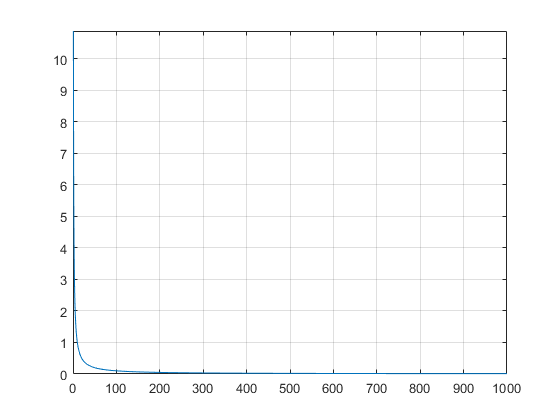

grid on

[tOpt, fObj] = newtonRaphsonMinimo(G, 40)

tOpt = 8.6255e+10

fObj = 1.1651e-10

## Costos para la Uniforme.

syms t
C1 = 500;
C2 = 100;
%exp con alpha = -0.01
a = 0;
b = 1000;

f = @(t) 1/(b-a)

f = function_handle with value:
    @(t)1/(b-a)


%fplot(f, [a,b])
F = matlabFunction(int(f, 0, t))

F = function_handle with value:
    @(t)t./1.0e+3


%fplot(F, [a,b])
R = @(t) 1- F(t)

R = function_handle with value:
    @(t)1-F(t)


%fplot(R, [a,b])
interR = matlabFunction(int(R, 0, t))

interR = function_handle with value:
    @(t)t.*(t-2.0e+3).*(-5.0e-4)


%fplot(interR, [a,b])

G = @(t) (C1*F(t)+C2*R(t))/interR(t)

G = function_handle with value:
    @(t)(C1*F(t)+C2*R(t))/interR(t)


fplot(G,[a+50,b+50])

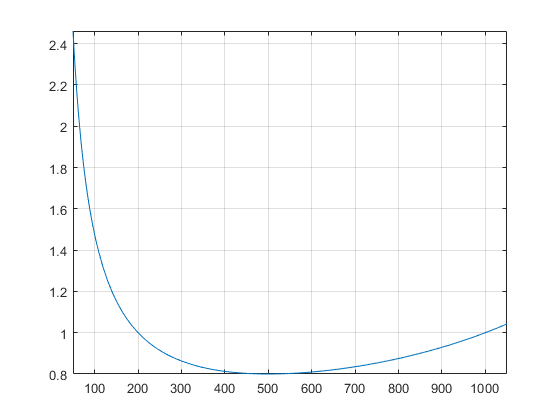

grid on

[tOpt, fObj] = newtonRaphsonMinimo(G, 500)

tOpt = 500.0000

fObj = 0.8000

## Mantenimiento y Remplazo Problema 6

syms t
C1 = 100; %Costo de mantenimiento Correctivo
C2 = 10; %Costo de mantenimineto Predictivo
F = @(t)  1-2*exp(-t)+exp(-2*t)

F = function_handle with value:
    @(t)1-2*exp(-t)+exp(-2*t)


R = @(t)  1-F(t)

R = function_handle with value:
    @(t)1-F(t)


f = @(t) matlabFunction(diff(F,t))

f = function_handle with value:
    @(t)matlabFunction(diff(F,t))


aux = int(R, 0, t)

$$aux = \frac{{\mathrm{e}}^{-2\,t}}{2}-2\,{\mathrm{e}}^{-t}+\frac{3}{2}$$

interR = matlabFunction(aux)

interR = function_handle with value:
    @(t)exp(-t).*-2.0+exp(t.*-2.0)./2.0+3.0./2.0



G = @(t) (C1*F(t)+C2*R(t))/interR(t)

G = function_handle with value:
    @(t)(C1*F(t)+C2*R(t))/interR(t)


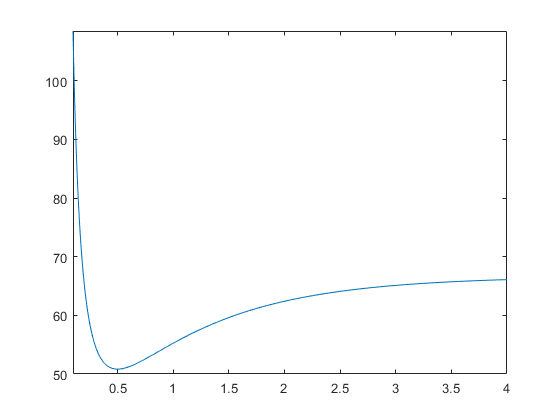

fplot(G, [0.1, 4])


[tOpt, fObj] = newtonRaphsonMinimo(G, 0.5)

tOpt = 0.5000

fObj = 50.8276

function [x, fx, i, min] = newtonRaphsonMinimo(f,x)
    %Parámetros iniciales
    max = 52;
    tol = sqrt(eps);
    i = 0;
    cond =  true;
    %Declaramos las funciones anónimas
    f = f;
    fs = sym(f);
    dfs = diff(fs);
    dfs2 = diff(dfs);
    df = matlabFunction(dfs);
    df2 = matlabFunction(dfs2);
    if nargin(df)<1
        error('Function has not second reivate')
    end
    if nargin(df2) < 1
        df2 = @(x) df2();
    end
    while cond
        xp = x;
        x = xp-df(xp)/df2(xp);
        cond = abs((x-xp)/x) > tol && i < max;
        i = i+1;
    end
    min = df2(x) > 0;  
    fx = f(x);
end
